# �Übungsblatt 1: Arbeiten mit Matlab

clear all
clc()


## Aufgabe 1



n=10

n = 10

A = zeros(n);
for i=1:n
    A(i,:) = i:(n+i-1);
end
A

A =      1     2     3     4     5     6     7     8     9    10
     2     3     4     5     6     7     8     9    10    11
     3     4     5     6     7     8     9    10    11    12
     4     5     6     7     8     9    10    11    12    13
     5     6     7     8     9    10    11    12    13    14
     6     7     8     9    10    11    12    13    14    15
     7     8     9    10    11    12    13    14    15    16
     8     9    10    11    12    13    14    15    16    17
     9    10    11    12    13    14    15    16    17    18
    10    11    12    13    14    15    16    17    18    19


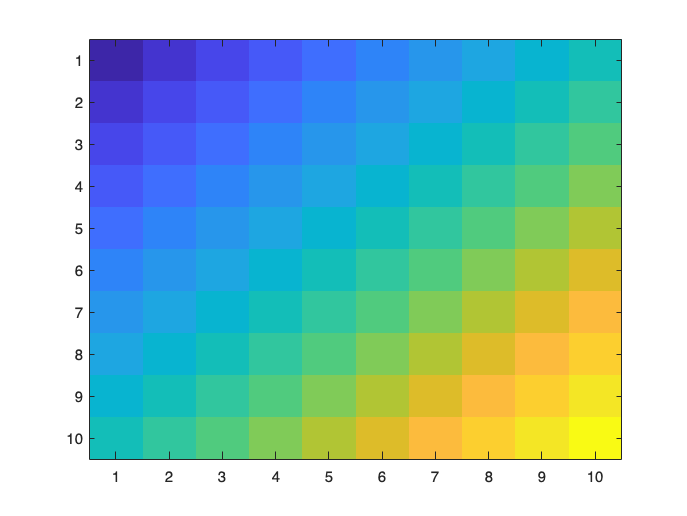

imagesc(A)

## Aufgabe 2

### Aufgabe 2.1

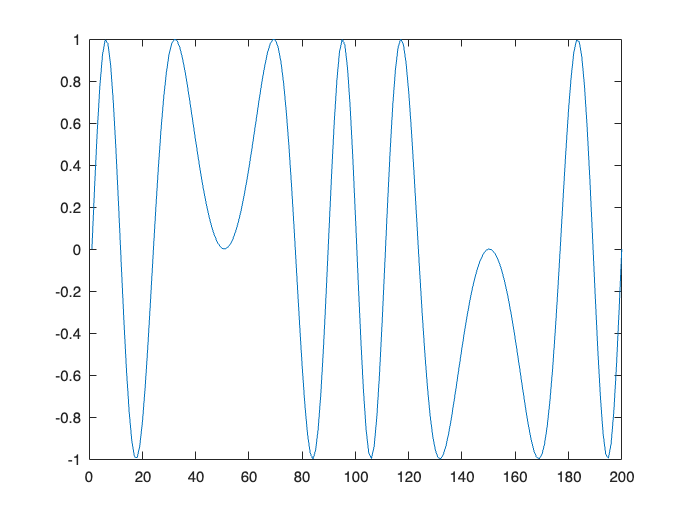

x = linspace(0,2*pi,200);
y1 = sin(3*pi*sin(x));
y2 = cos(exp(0.7*x));

plot(y1)

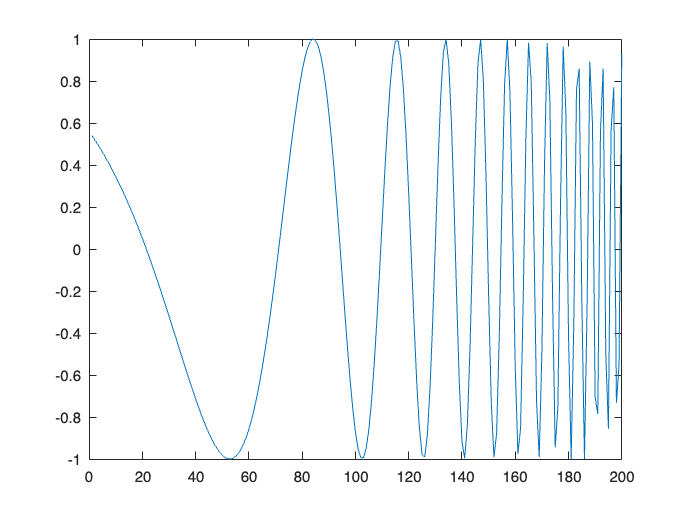

plot(y2)

### Aufgabe 2.2

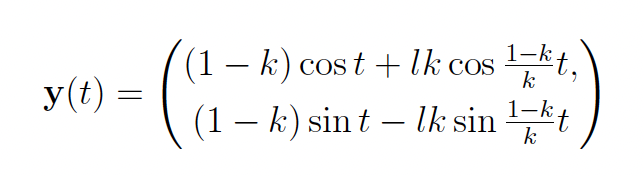

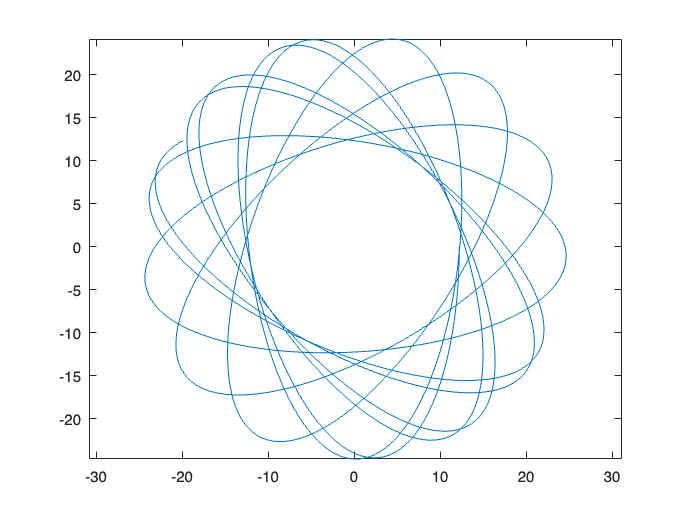

t=linspace(0,20*pi,1000);
k=7.23;
l=2.55;
y1=(1-k)*cos(t)+l*k*cos(((1-k)/k)*t);
y2=(1-k)*sin(t)+l*k*sin(((1-k)/k)*t);
plot(y1,y2)
axis equal

## Aufgabe 3

#### Aufgabe 3.1

pwfunc(0.5)

pwfunc is not found in the current folder or on the MATLAB path, but exists in:
    /Users/simonmacbook/Creative Cloud Files/WiSe23_24/Numerik_pDGL/Paket 0

Change the MATLAB current folder or add its folder to the MATLAB path.

x=linspace(-2,3,1000);
y=zeros(length(x));
for i=1:length(x)
    y(i)=pwfunc(x(i));
end

plot(x,y)

Vektorisiert

fplot(@pwfuncv,[-2,3])

#### Aufgabe 3.2

als anonyme Funktion

fa=@(a) @(x) (exp(a.*x))
for a=-2:0.2:2
    fax=fa(a);
    fplot(fax,[-2,2])
    hold on
end
hold off

als m Datei

for a=-2:0.2:2
    fam=fa(a);
    fplot(fam,[-2,2])
    hold on
end
hold off